% data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv', 'ReadVariableNames',1);
% dates = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv');
% Confounding = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Confounding/Confounding_Dataset.csv', 'ReadVariableNames',1);
% AQI_data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/AQI_Features.csv')

data = readtable('Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv', 'ReadVariableNames',1);
dates = readtable('Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv');
Confounding = readtable('Datasets/Confounding/Confounding_Dataset.csv', 'ReadVariableNames',1);
Features = readtable('Datasets/AQI_Features.csv');
AQI_Classes = Features.AQI_Class_KM; 

spectral_class = zeros(832,0);

NC = zeros(832,3);
NC(AQI_Classes==1,2) = 1;
NC(AQI_Classes==2,1) = 1;
NC(AQI_Classes==2,2) = 1;
NC(AQI_Classes==3,1) = 1;

Total_Population = (Confounding.TOT_POP);
cases = table2array(data(:,12:173));
cases = cases./Total_Population;

US = 256;
[rC, cC] = size(cases);
splines = zeros(rC,US);

for t = 1:rC
    casesS = cases(t,:);
    casesS = nonzeros(casesS); % non-zero cases 
    if length(casesS)>1
        x = [1:length(casesS)]';  % number of days since first case 
        f = fit(x, casesS, 'cubicinterp');
        xeval = linspace(1, length(casesS), US);
        sp_eval = f(xeval)';
        splines(t,:)= sp_eval;
    end 
end 

exemplar = mean(splines);
diff_splines = zeros(rC,US);

for t = 1:rC
    diff_splines(t,:) = splines(t,:)-exemplar;
end

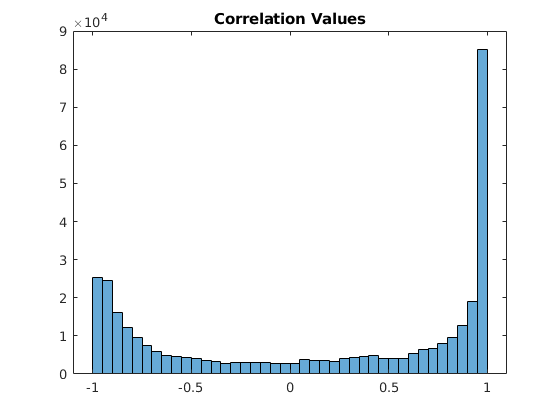

% Linear Correlation btwn cases
xcor_total = corrcoef(diff_splines');
NodeNames = string([1:rC]);
NodeNames = cellstr(NodeNames);

new_diag = zeros(1,rC);
xcor_total(find(eye(size(xcor_total))))=new_diag; %removing self edges

G = graph(xcor_total);
%plot(G)

G_WEIGHTS = G.Edges.Weight;
edges = [-1:0.05:1];
h = histogram(G_WEIGHTS, edges);
title('Correlation Values')

% Edgeless Nodes vs Correlation Threshold Calculations 

threshL = [0.8:0.01:1];
num_zero_connections = zeros(size(threshL));

for t=1:length(threshL)
    xcor_thresh = xcor_total;
    xcor_thresh(xcor_thresh<threshL(t))=0;
    G = graph(xcor_thresh);
    D = degree(G);
    zero_con_idx = find(D==0);
    num_zero_connections(t) = length(zero_con_idx);
end 

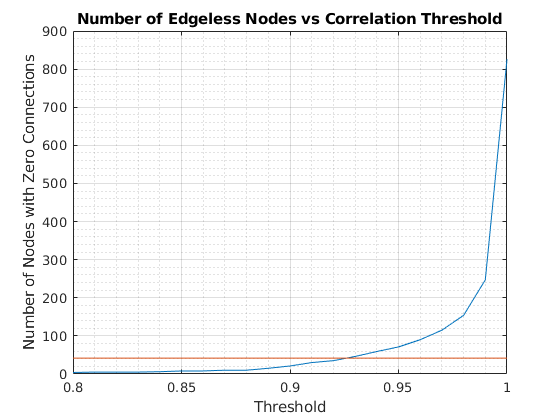

% Edgeless Nodes vs Correlation Threshold Plot 

five_pct = (832*0.05)*ones(size(threshL));
plot(threshL, num_zero_connections)
hold on; 
plot(threshL, five_pct)
xlabel('Threshold')
ylabel('Number of Nodes with Zero Connections')
title('Number of Edgeless Nodes vs Correlation Threshold')
hold off; 
grid on; 
grid minor; 

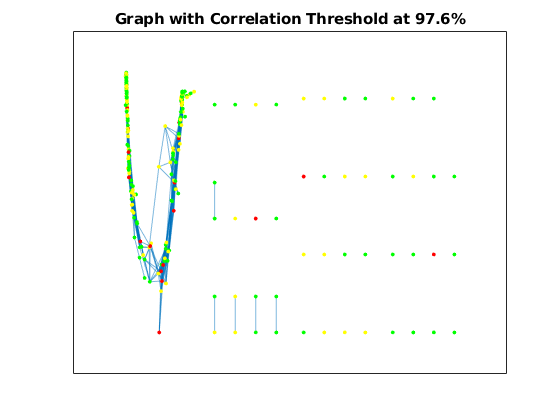

xcor_thresh = xcor_total;
thresh = 0.925; % 5 pct edgeless 
%thresh = 0.9564; % 10 pct edgeless
%thresh = 0.98
xcor_thresh(xcor_thresh<thresh)=0;

xcor_thresh = 1-xcor_thresh; 
xcor_thresh(xcor_thresh==1)=0;

G = graph(xcor_thresh, NodeNames);
%plot(G, 'NodeColor', NC, 'NodeLabel', NodeNames);
plot(G, 'NodeColor', NC);
title('Graph with Correlation Threshold at 97.6%')
grid on;
grid minor; 

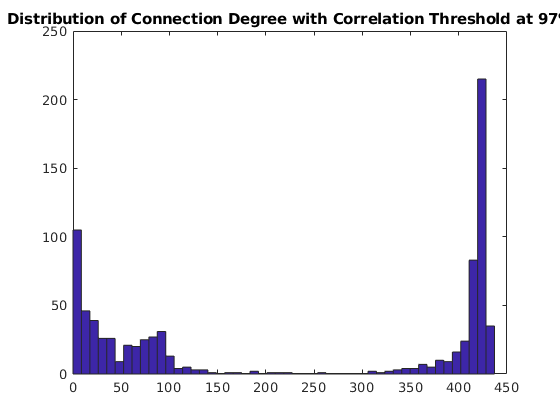


D = degree(G);
hist(D, 50);
title('Distribution of Connection Degree with Correlation Threshold at 97%')

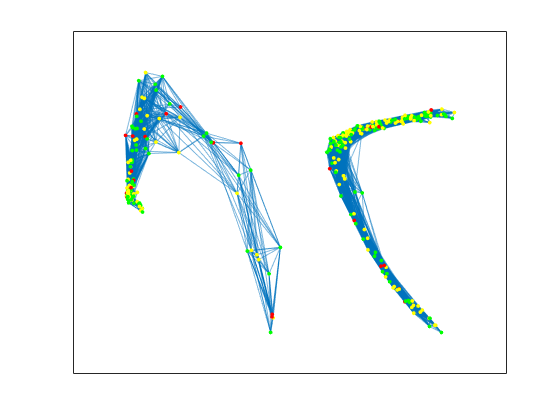


cut_degree = 10; 
min_cuts_idx = find(D<=cut_degree);
NC_cut = NC(D>cut_degree,:);
G_cut = rmnode(G, min_cuts_idx);
plot(G_cut, 'NodeColor',NC_cut)
grid on;
grid minor; 

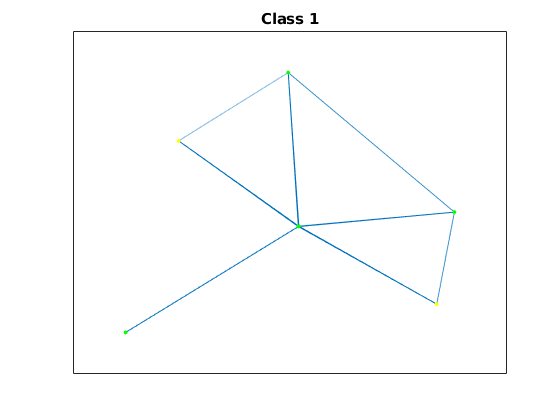

% Spectral clustering the cut graph 

G_cut_Sim = adjacency(G_cut, 'weighted');
G_cut_Sim_Full = full(G_cut_Sim);

% Cluster into Groups 
SC = spectralcluster(G_cut_Sim_Full,6);

c1 = subgraph(G_cut, find(SC==1));
c1_idx = str2double(table2array(c1.Nodes));
spectral_class(c1_idx) = 1;
NC_c1 = NC(c1_idx,:);
plot(c1, 'NodeColor', NC_c1)
title('Class 1')

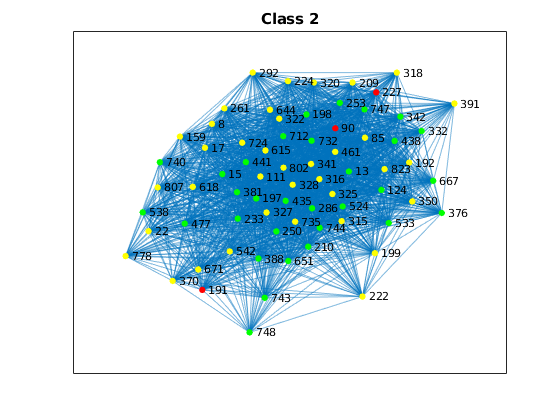


c2 = subgraph(G_cut, find(SC==2));
c2_idx = str2double(table2array(c2.Nodes));
spectral_class(c1_idx) = 2;
NC_c2 = NC(c2_idx,:);
plot(c2, 'NodeColor', NC_c2)
title('Class 2')

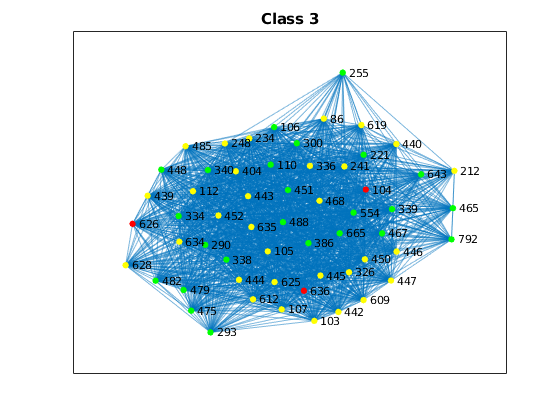


c3 = subgraph(G_cut, find(SC==3));
c3_idx = str2double(table2array(c3.Nodes));
spectral_class(c3_idx) = 3;
NC_c3 = NC(c3_idx,:);
plot(c3, 'NodeColor', NC_c3)
title('Class 3')

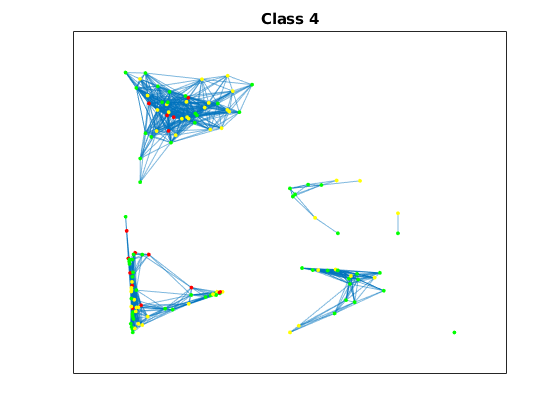


c4 = subgraph(G_cut, find(SC==4));
c4_idx = str2double(table2array(c4.Nodes));
spectral_class(c4_idx) = 4;
NC_c4 = NC(c4_idx,:);
plot(c4, 'NodeColor', NC_c4)
title('Class 4')

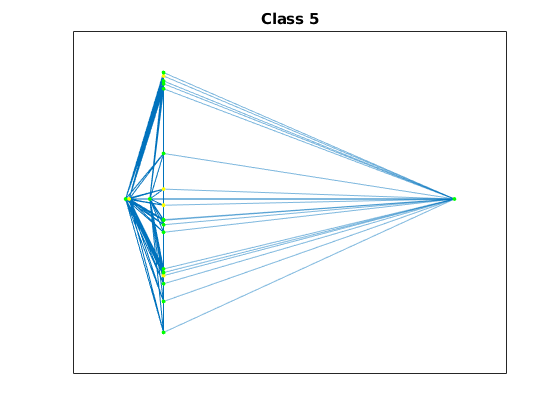


c5 = subgraph(G_cut, find(SC==5));
c5_idx = str2double(table2array(c5.Nodes));
spectral_class(c5_idx) = 5;
NC_c5 = NC(c5_idx,:);
plot(c5, 'NodeColor', NC_c5)
title('Class 5')

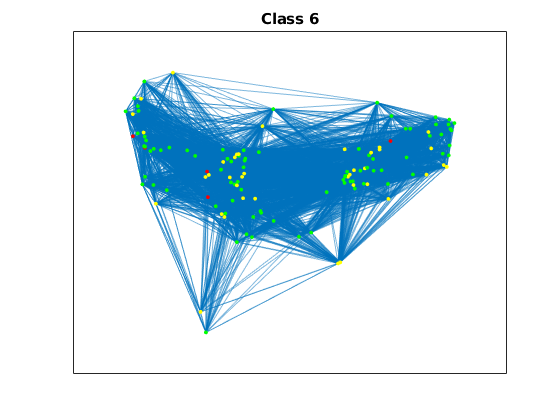


c6 = subgraph(G_cut, find(SC==6));
c6_idx = str2double(table2array(c6.Nodes));
spectral_class(c6_idx) = 6;
NC_c6 = NC(c6_idx,:);
plot(c6, 'NodeColor', NC_c6)
title('Class 6')

CS = Features.CS;
SpectralClass = spectral_class';
T = table(CS, SpectralClass);
%writetable(T,'Datasets/Spectral_Clustering_Classes.csv')